## Random Forest Tests

### Initialise

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardisedReducedFeatures;
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
            isStandardised: 1
          isRemovedFeature: 1



### Check Random Forest Analysis Code Works

hyperParameters = RFHyperparameters.getHyperQuickInstance();

rfHyperparameters =   RFHyperparameters with properties:

      features: [2 4]
         trees: 25
         folds: [1 2]
    randomSeed: 122


rfClass = RandomForestClass(hyperParameters);
rfClass.debug = true;
results = rfClass.performAnalysis(letterDataset, "RFQuickTest.csv");

Starting Random Forest analysis...
Misclassified 179 entries out of 3200. 5.5938 pct
	Training loss: 0.01. Test Loss: 0.09 Oob Error: 0.18
	Precision: 0.9435 Recall: 0.9441 Accuracy: 0.9441 F1: 0.9438


errOob = 0.1825

accuracies = 0.9441

tree 25 feature 2 trainError 0.0100 test error 0.0855 oob error 0.1825 fold 1  of 1 	Samples: T I D N G
Misclassified 160 entries out of 3200. 5.0000 pct
	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.19
	Precision: 0.9491 Recall: 0.9500 Accuracy: 0.9500 F1: 0.9496


errOob = 0.1886

accuracies = 0.9500

tree 25 feature 2 trainError 0.0110 test error 0.0821 oob error 0.1886 fold 1  of 2 	Samples: I N G X O
Misclassified 173 entries out of 3200. 5.4063 pct
	Training loss: 0.01. Test Loss: 0.09 Oob Error: 0.18
	Precision: 0.9463 Recall: 0.9462 Accuracy: 0.9459 F1: 0.9462


errOob =     0.1886    0.1832


accuracies =     0.9500    0.9459


tree 25 feature 2 trainError 0.0102 test error 0.0850 oob error 0.1832 fold 2  of 2 	Samples: T I D N G
Misclassified 172 entries out of 3200. 5.3750 pct
	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18
	Precision: 0.9468 Recall: 0.9480 Accuracy: 0.9463 F1: 0.9474


errOob = 0.1750

accuracies = 0.9463

tree 25 feature 4 trainError 0.0085 test error 0.0775 oob error 0.1750 fold 1  of 1 	Samples: T I D N G
Misclassified 140 entries out of 3200. 4.3750 pct
	Training loss: 0.01. Test Loss: 0.07 Oob Error: 0.17
	Precision: 0.9556 Recall: 0.9561 Accuracy: 0.9563 F1: 0.9558


errOob = 0.1720

accuracies = 0.9563

tree 25 feature 4 trainError 0.0079 test error 0.0709 oob error 0.1720 fold 1  of 2 	Samples: T I D N G
Misclassified 173 entries out of 3200. 5.4063 pct
	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.17
	Precision: 0.9447 Recall: 0.9455 Accuracy: 0.9459 F1: 0.9451


errOob =     0.1720    0.1714


accuracies =     0.9563    0.9459


tree 25 feature 4 trainError 0.0078 test error 0.0753 oob error 0.1714 fold 2  of 2 	Samples: T I D G A


disp(results.resultsTable);

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________

       2        25       1              1                 0.01         0.0855         0.1825        0.9441          0.9435        0.9441      0.9438       3200         6.9531   
       2        25     

### Train TreeBagger Model

rng(1);
model = TreeBagger(50, letterDataset.trainTable, "TargetAscii", ...
  "OOBPrediction", "On", ...
  "OOBPredictorImportance", "On", ...
  'PredictorSelection','curvature', ...
  "Method", "classification")

model =   TreeBagger
Ensemble with 50 bagged decision trees:
                    Training X:           [16000x12]
                    Training Y:            [16000x1]
                        Method:       classification
                 NumPredictors:                   12
         NumPredictorsToSample:                    4
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             'A'             'B'             'C'             'D'             'E'             'F'             'G'             'H'             'I'             'J'             'K'             'L'             'M'             'N'             'O'             'P'             'Q'          

### Plot out-of-bag error / number of trees

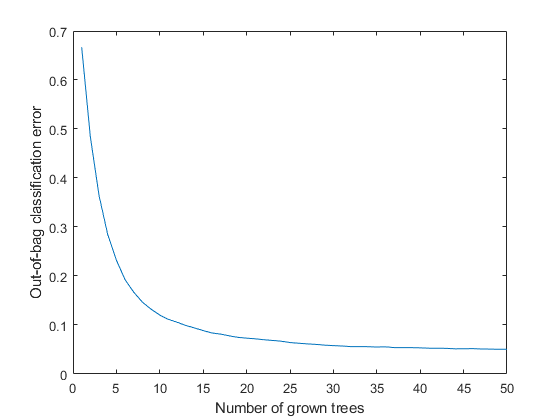

figure;
oobErrorBaggedEnsemble = oobError(model);
plot(oobErrorBaggedEnsemble)
xlabel 'Number of grown trees';
ylabel 'Out-of-bag classification error';

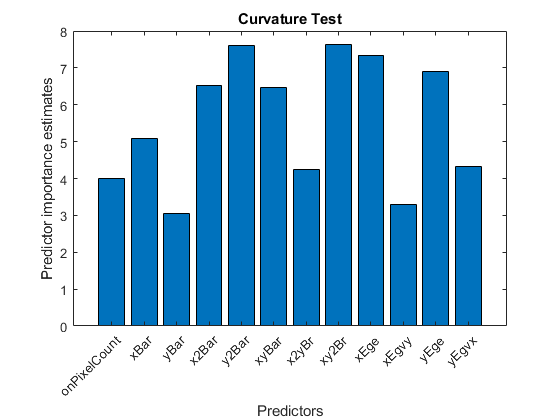


% plot predictor importances
imp = model.OOBPermutedPredictorDeltaError;

figure;
bar(imp);
title('Curvature Test');
ylabel('Predictor importance estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = model.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

### Notes

TreeBagger has several properties of interest:

- `NumPredictorsToSample: number of features to randomly select for each tree, default sqrt(num classes)`

- `NumTrees: the number of trees in the forest`

- `Prior: prior distribution of the classes, this is set to the empirical distribution of the entire training dataset classes`

`Number of trees in the ensemble: Khoshgoftaar (2007) a default value of 100 for trees is good.`

`Braiman (2001): more trees will give better results without overfitting on the validation set.`

`Number of random features for splitting at each step: Khoshgoftarr (2007) (log2 * numFeatures + 1). Matlab uses sqrt(numFeatures)`